# **R-factor: Visualize geomechanical changes Model 6**

## Introduction

Several models were generated with COMSOL

- Model 5 - Homogeneous model

- Model 6 - Groningen model, different permeability on top and bottom of the reservoir

- Model 7 - Groningen model, the same permeability on top and bottom of the reservoir

This script visualize changes due to fluid production for Model 5

**Authors**: Ivan Abakumov

**Publication date**: 28th of October 2019

**E-mail**: ivan.abakumov@fu-berlin.de

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Load G-file and comsol data

Results = MLD('/home/ivan/Desktop/Comsol/My_model_6_results.mat');
G = MLD('/home/ivan/Desktop/Comsol/My_model_6_G_file.mat');

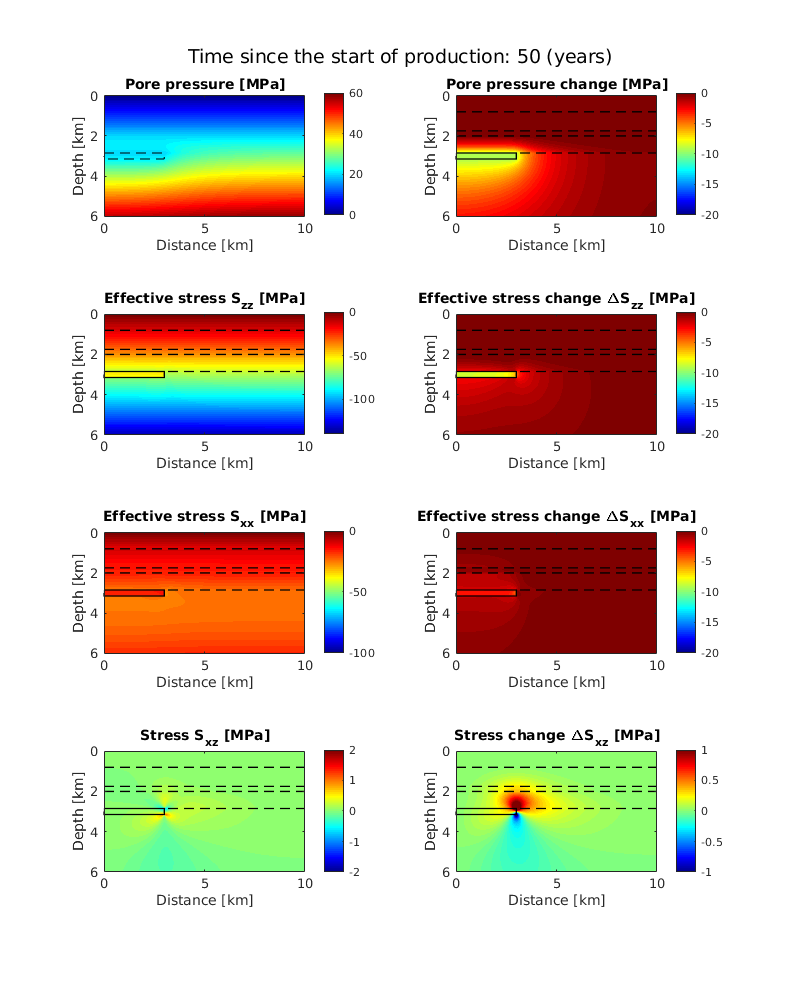

tt = 101;

figure(223)
fig = figure('Position', [1 1 800 1000]);
subplot(4,2,1)
imagesc(G.xx/1e3, G.zz/1e3, Results.pressure(:,:,tt)'/1e6)
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '--')
plot(linspace(0,0,101),linspace(0,3,101),'w-')
colormap jet
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Pore pressure [MPa]')
caxis([0 60])

subplot(4,2,3)
imagesc(G.xx/1e3, G.zz/1e3, Results.stress_y(:,:,tt)'/1e6)
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,0,101),linspace(0,3,101),'w-')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,0,101),linspace(0,3,101),'w-')
colormap jet
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Effective stress S_{zz} [MPa]')
caxis([-140 0])

subplot(4,2,5)
imagesc(G.xx/1e3, G.zz/1e3, Results.stress_x(:,:,tt)'/1e6)
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,0,101),linspace(0,3,101),'w-')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap jet
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Effective stress S_{xx} [MPa]')
caxis([-100 0])

subplot(4,2,7)
imagesc(G.xx/1e3, G.zz/1e3, Results.stress_xy(:,:,tt)'/1e6)
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,0,101),linspace(0,3,101),'w-')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap jet
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Stress S_{xz} [MPa]')
caxis([-2 2])

subplot(4,2,2)
imagesc(G.xx/1e3, G.zz/1e3, (Results.pressure(:,:,tt)'-Results.pressure(:,:,1)')/1e6)
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,0,101),linspace(0,3,101),'w-')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap jet
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Pore pressure change [MPa]')
caxis([-20 0])

subplot(4,2,4)
imagesc(G.xx/1e3, G.zz/1e3, (Results.stress_y(:,:,tt)'-Results.stress_y(:,:,1)')/1e6)
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,0,101),linspace(0,3,101),'w-')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap jet
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title(['Effective stress change \DeltaS_{zz} [MPa]'])
caxis([-20 0])

subplot(4,2,6)
imagesc(G.xx/1e3, G.zz/1e3, (Results.stress_x(:,:,tt)'-Results.stress_x(:,:,1)')/1e6)
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,0,101),linspace(0,3,101),'w-')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap jet
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Effective stress change \DeltaS_{xx} [MPa]')
caxis([-20 0])

subplot(4,2,8)
imagesc(G.xx/1e3, G.zz/1e3, (Results.stress_xy(:,:,tt)'-Results.stress_xy(:,:,1)')/1e6)
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,0,101),linspace(0,3,101),'w-')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap jet
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Stress change \DeltaS_{xz} [MPa]')
caxis([-1 1])

sgtitle(['Time since the start of production: ' num2str(G.tt(tt),2) ' (years)'] )

## Plot displacement 1 

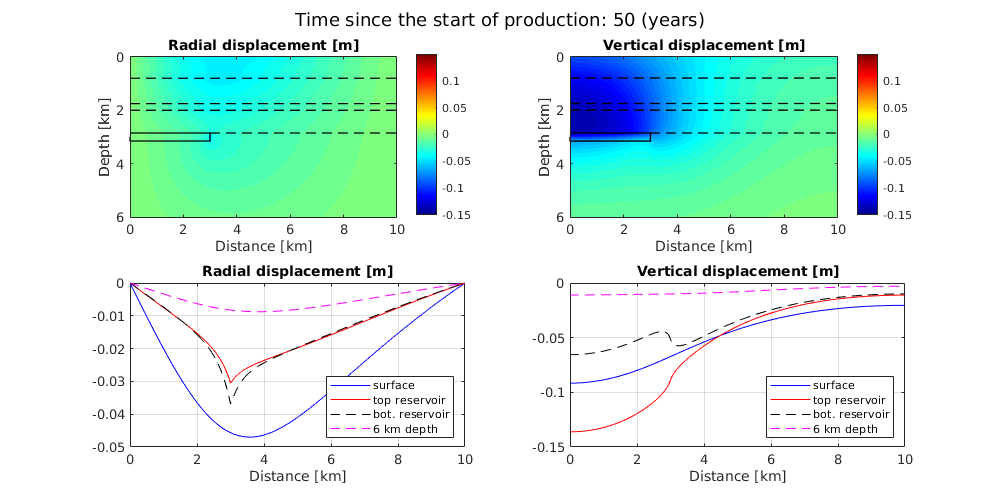

tt = 101;

figure(2232)
fig = figure('Position', [1 1 1000 500]);
subplot(2,2,1)
imagesc(G.xx/1e3, G.zz/1e3, Results.disp_x(:,:,tt)'-Results.disp_x(:,:,1)')
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,0,101),linspace(0,3,101),'w-')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap jet
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Radial displacement [m]')
caxis([-0.15 0.15])

subplot(2,2,2)
imagesc(G.xx/1e3, G.zz/1e3, Results.disp_y(:,:,tt)' - Results.disp_y(:,:,1)')
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,0,101),linspace(0,3,101),'w-')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap jet
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Vertical displacement [m]')
caxis([-0.15 0.15])

subplot(2,2,3)
plot(G.xx/1e3, Results.disp_x(:,1,tt)'-Results.disp_x(:,1,1)', 'b')
hold on
plot(G.xx/1e3, Results.disp_x(:,286,tt)'-Results.disp_x(:,286,1)', 'r')
plot(G.xx/1e3, Results.disp_x(:,316,tt)'-Results.disp_x(:,316,1)', 'k--')
plot(G.xx/1e3, Results.disp_x(:,601,tt)'-Results.disp_x(:,601,1)', 'm--')
xlabel('Distance [km]')
title('Radial displacement [m]')
legend('surface','top reservoir','bot. reservoir', '6 km depth', 'Location', 'southeast')
grid on


subplot(2,2,4)
plot(G.xx/1e3, Results.disp_y(:,1,tt)'-Results.disp_y(:,1,1)', 'b')
hold on
plot(G.xx/1e3, Results.disp_y(:,286,tt)'-Results.disp_y(:,286,1)', 'r')
plot(G.xx/1e3, Results.disp_y(:,316,tt)'-Results.disp_y(:,316,1)', 'k--')
plot(G.xx/1e3, Results.disp_y(:,601,tt)'-Results.disp_y(:,601,1)', 'm--')
xlabel('Distance [km]')
title('Vertical displacement [m]')
legend('surface','top reservoir','bot. reservoir', '6 km depth', 'Location', 'southeast')
grid on


sgtitle(['Time since the start of production: ' num2str(G.tt(tt),2) ' (years)'] )

## Plot displacement 2

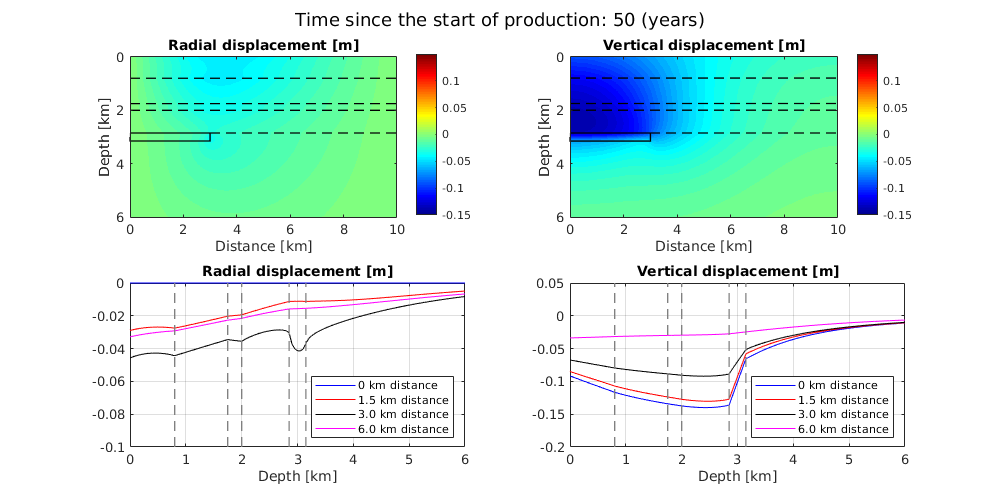

tt = 101;

figure(2233)
fig = figure('Position', [1 1 1000 500]);
subplot(2,2,1)
imagesc(G.xx/1e3, G.zz/1e3, Results.disp_x(:,:,tt)'-Results.disp_x(:,:,1)')
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,0,101),linspace(0,3,101),'w-')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap jet
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Radial displacement [m]')
caxis([-0.15 0.15])

subplot(2,2,2)
imagesc(G.xx/1e3, G.zz/1e3, Results.disp_y(:,:,tt)' - Results.disp_y(:,:,1)')
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,0,101),linspace(0,3,101),'w-')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap jet
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Vertical displacement [m]')
caxis([-0.15 0.15])

subplot(2,2,3)
plot(G.zz/1e3, Results.disp_x(1,:,tt)'-Results.disp_x(1,:,1)', 'b')
hold on
plot(G.zz/1e3, Results.disp_x(151,:,tt)'-Results.disp_x(151,:,1)', 'r')
plot(G.zz/1e3, Results.disp_x(301,:,tt)'-Results.disp_x(301,:,1)', 'k-')
plot(G.zz/1e3, Results.disp_x(601,:,tt)'-Results.disp_x(601,:,1)', 'm-')
plot(linspace(800,800,100)/1e3,  linspace(-0.1,0,100),  '--k', 'LineWidth',1, 'Color',[0.5 0.5 0.5])
plot(linspace(1750,1750,100)/1e3,linspace(-0.1,0,100), '--k', 'LineWidth',1, 'Color',[0.5 0.5 0.5])
plot(linspace(1750,1750,100)/1e3,linspace(-0.1,0,100), '--k', 'LineWidth',1, 'Color',[0.5 0.5 0.5])
plot(linspace(2000,2000,100)/1e3,linspace(-0.1,0,100), '--k', 'LineWidth',1,  'Color',[0.5 0.5 0.5])
plot(linspace(2850,2850,100)/1e3,linspace(-0.1,0,100), '--k', 'LineWidth',1,  'Color',[0.5 0.5 0.5])
plot(linspace(3150,3150,100)/1e3,linspace(-0.1,0,100), '--k', 'LineWidth',1,  'Color',[0.5 0.5 0.5])
axis([0 6 -0.1 0])
xlabel('Depth [km]')
title('Radial displacement [m]')
legend('0 km distance','1.5 km distance','3.0 km distance', '6.0 km distance', 'Location', 'southeast')
grid on


subplot(2,2,4)
plot(G.zz/1e3, Results.disp_y(1,:,tt)'-Results.disp_y(1,:,1)', 'b')
hold on
plot(G.zz/1e3, Results.disp_y(151,:,tt)'-Results.disp_y(151,:,1)', 'r')
plot(G.zz/1e3, Results.disp_y(301,:,tt)'-Results.disp_y(301,:,1)', 'k-')
plot(G.zz/1e3, Results.disp_y(601,:,tt)'-Results.disp_y(601,:,1)', 'm-')
plot(linspace(800,800,100)/1e3,  linspace(-0.20,0.05,100),  '--k', 'LineWidth',1, 'Color',[0.5 0.5 0.5])
plot(linspace(1750,1750,100)/1e3,linspace(-0.20,0.05,100), '--k', 'LineWidth',1, 'Color',[0.5 0.5 0.5])
plot(linspace(1750,1750,100)/1e3,linspace(-0.20,0.05,100), '--k', 'LineWidth',1, 'Color',[0.5 0.5 0.5])
plot(linspace(2000,2000,100)/1e3,linspace(-0.20,0.05,100), '--k', 'LineWidth',1,  'Color',[0.5 0.5 0.5])
plot(linspace(2850,2850,100)/1e3,linspace(-0.20,0.05,100), '--k', 'LineWidth',1,  'Color',[0.5 0.5 0.5])
plot(linspace(3150,3150,100)/1e3,linspace(-0.20,0.05,100), '--k', 'LineWidth',1,  'Color',[0.5 0.5 0.5])
axis([0 6 -0.20 0.05])
xlabel('Depth [km]')
title('Vertical displacement [m]')
legend('0 km distance','1.5 km distance','3.0 km distance', '6.0 km distance', 'Location', 'southeast')
grid on


sgtitle(['Time since the start of production: ' num2str(G.tt(tt),2) ' (years)'] )

## Plot pressure vs displacement

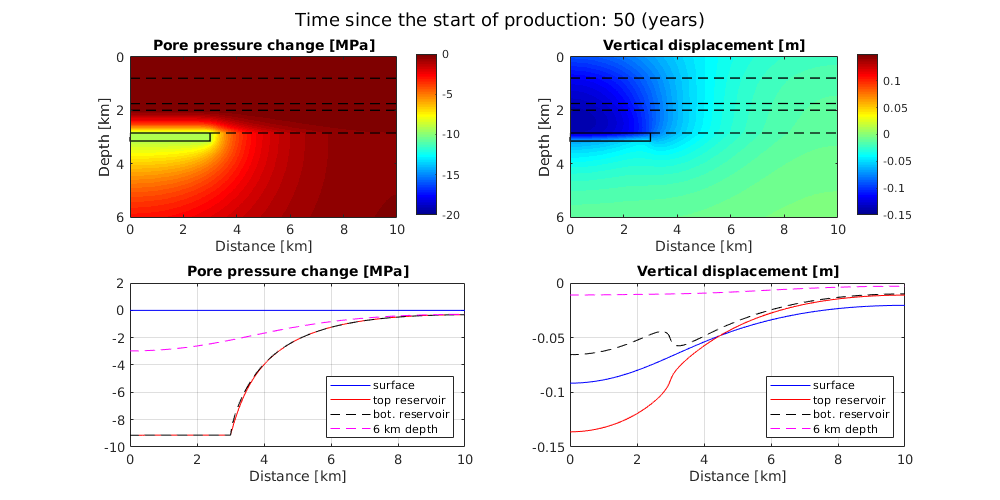

tt = 101;

figure(2232)
fig = figure('Position', [1 1 1000 500]);
subplot(2,2,1)
imagesc(G.xx/1e3, G.zz/1e3, (Results.pressure(:,:,tt)'-Results.pressure(:,:,1)')/1e6)
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,0,101),linspace(0,3,101),'w-')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,0,101),linspace(0,3,101),'w-')
colormap jet
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Pore pressure change [MPa]')
caxis([-20 0])

subplot(2,2,2)
imagesc(G.xx/1e3, G.zz/1e3, Results.disp_y(:,:,tt)' - Results.disp_y(:,:,1)')
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,0,101),linspace(0,3,101),'w-')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap jet
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Vertical displacement [m]')
caxis([-0.15 0.15])

subplot(2,2,3)
plot(G.xx/1e3, (Results.pressure(:,1,tt)'-Results.pressure(:,1,1)')/1e6, 'b')
hold on
plot(G.xx/1e3, (Results.pressure(:,286,tt)'-Results.pressure(:,286,1)')/1e6, 'r')
plot(G.xx/1e3, (Results.pressure(:,316,tt)'-Results.pressure(:,316,1)')/1e6, 'k--')
plot(G.xx/1e3, (Results.pressure(:,601,tt)'-Results.pressure(:,601,1)')/1e6, 'm--')
xlabel('Distance [km]')
grid on
title('Pore pressure change [MPa]')
legend('surface','top reservoir','bot. reservoir', '6 km depth', 'Location', 'southeast')

subplot(2,2,4)
plot(G.xx/1e3, Results.disp_y(:,1,tt)'-Results.disp_y(:,1,1)', 'b')
hold on
plot(G.xx/1e3, Results.disp_y(:,286,tt)'-Results.disp_y(:,286,1)', 'r')
plot(G.xx/1e3, Results.disp_y(:,316,tt)'-Results.disp_y(:,316,1)', 'k--')
plot(G.xx/1e3, Results.disp_y(:,601,tt)'-Results.disp_y(:,601,1)', 'm--')
xlabel('Distance [km]')
grid on
title('Vertical displacement [m]')
legend('surface','top reservoir','bot. reservoir', '6 km depth', 'Location', 'southeast')



sgtitle(['Time since the start of production: ' num2str(G.tt(tt),2) ' (years)'] )

## Plot pressure vs displacement - 2

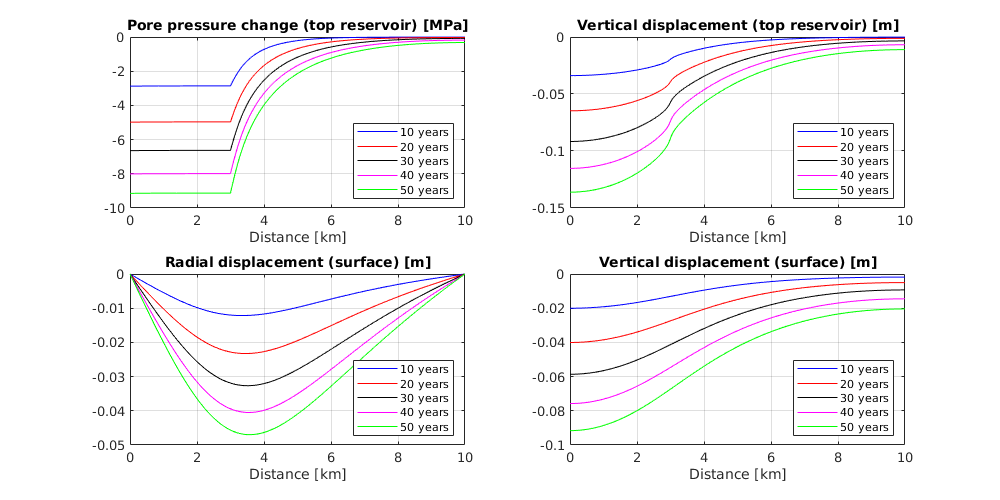

figure(2232)
fig = figure('Position', [1 1 1000 500]);
subplot(2,2,1)
plot(G.xx/1e3, (Results.pressure(:,286,21)'-Results.pressure(:,286,1)')/1e6, 'b')
hold on
plot(G.xx/1e3, (Results.pressure(:,286,41)'-Results.pressure(:,286,1)')/1e6, 'r')
plot(G.xx/1e3, (Results.pressure(:,286,61)'-Results.pressure(:,286,1)')/1e6, 'k')
plot(G.xx/1e3, (Results.pressure(:,286,81)'-Results.pressure(:,286,1)')/1e6, 'm')
plot(G.xx/1e3, (Results.pressure(:,286,101)'-Results.pressure(:,286,1)')/1e6, 'g')
xlabel('Distance [km]')
grid on
title('Pore pressure change (top reservoir) [MPa]')
legend('10 years','20 years','30 years','40 years','50 years', 'Location', 'southeast')


subplot(2,2,2)
plot(G.xx/1e3, Results.disp_y(:,286,21)'-Results.disp_y(:,286,1)', 'b')
hold on
plot(G.xx/1e3, Results.disp_y(:,286,41)'-Results.disp_y(:,286,1)', 'r')
plot(G.xx/1e3, Results.disp_y(:,286,61)'-Results.disp_y(:,286,1)', 'k')
plot(G.xx/1e3, Results.disp_y(:,286,81)'-Results.disp_y(:,286,1)', 'm')
plot(G.xx/1e3, Results.disp_y(:,286,101)'-Results.disp_y(:,286,1)', 'g')
xlabel('Distance [km]')
title('Vertical displacement (top reservoir) [m]')
legend('10 years','20 years','30 years','40 years','50 years', 'Location', 'southeast')
grid on 

subplot(2,2,3)
plot(G.xx/1e3, Results.disp_x(:,1,21)'-Results.disp_x(:,1,1)', 'b')
hold on
plot(G.xx/1e3, Results.disp_x(:,1,41)'-Results.disp_x(:,1,1)', 'r')
plot(G.xx/1e3, Results.disp_x(:,1,61)'-Results.disp_x(:,1,1)', 'k')
plot(G.xx/1e3, Results.disp_x(:,1,81)'-Results.disp_x(:,1,1)', 'm')
plot(G.xx/1e3, Results.disp_x(:,1,101)'-Results.disp_x(:,1,1)', 'g')
xlabel('Distance [km]')
title('Radial displacement (surface) [m]')
legend('10 years','20 years','30 years','40 years','50 years', 'Location', 'southeast')
grid on

subplot(2,2,4)
plot(G.xx/1e3, Results.disp_y(:,1,21)'-Results.disp_y(:,1,1)', 'b')
hold on
plot(G.xx/1e3, Results.disp_y(:,1,41)'-Results.disp_y(:,1,1)', 'r')
plot(G.xx/1e3, Results.disp_y(:,1,61)'-Results.disp_y(:,1,1)', 'k')
plot(G.xx/1e3, Results.disp_y(:,1,81)'-Results.disp_y(:,1,1)', 'm')
plot(G.xx/1e3, Results.disp_y(:,1,101)'-Results.disp_y(:,1,1)', 'g')
xlabel('Distance [km]')
title('Vertical displacement (surface) [m]')
legend('10 years','20 years','30 years','40 years','50 years', 'Location', 'southeast')
grid on 